% Build Color Matricies
desiredSize = [512 512];
black3DArray = fnBuildCDataFromConstantColor([0.0 0.0 0.0], desiredSize);
darkgrey3DArray = fnBuildCDataFromConstantColor([0.3 0.3 0.3], desiredSize);
lightgrey3DArray = fnBuildCDataFromConstantColor([0.6 0.6 0.6], desiredSize);

red3DArray = fnBuildCDataFromConstantColor([1.0 0.0 0.0], desiredSize);
green3DArray = fnBuildCDataFromConstantColor([0.0 1.0 0.0], desiredSize);
blue3DArray = fnBuildCDataFromConstantColor([0.0 0.0 1.0], desiredSize);

darkRed3DArray = fnBuildCDataFromConstantColor([0.6 0.0 0.0], desiredSize);
darkGreen3DArray = fnBuildCDataFromConstantColor([0.0 0.6 0.0], desiredSize);
darkBlue3DArray = fnBuildCDataFromConstantColor([0.0 0.0 0.6], desiredSize);


% colorsArray = {lightgrey3DArray, black3DArray, red3DArray, green3DArray, blue3DArray};


% tempConjunctionMask = logical(final_data_explorer_obj.amalgamationMasks.AlphaConjunctionMask);

figure
clf
% hold on
for i = 1:final_data_explorer_obj.num_cellROIs
    temp.curr_edge_mask = squeeze(final_data_explorer_obj.roiMasks.Edge(i,:,:));
    temp.curr_edge_mask = temp.curr_edge_mask + squeeze(final_data_explorer_obj.roiMasks.OutsetEdge0(i,:,:));
    
    
    im = image('CData', temp.curr_edge_mask, 'AlphaData', temp.curr_edge_mask);
%     im.AlphaData = 0.5;
end


## Inset Debugging/Testing

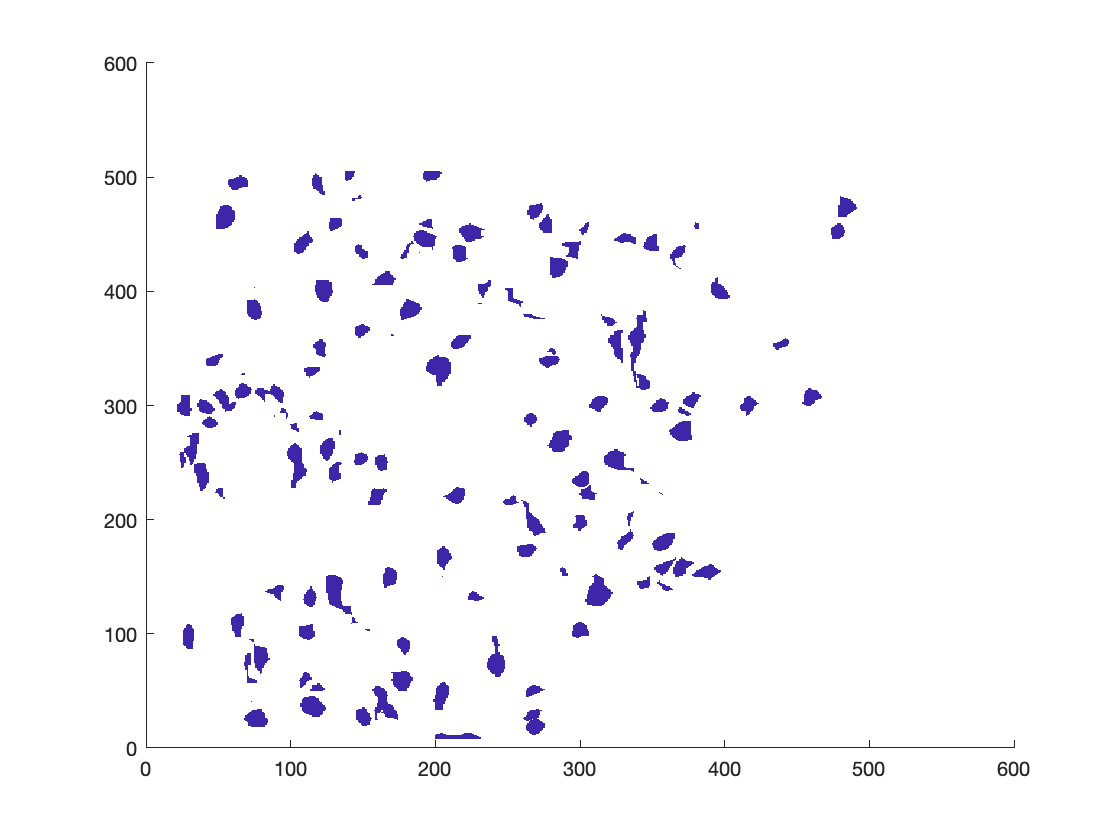

figure
clf
% hold on
for i = 1:final_data_explorer_obj.num_cellROIs
%     temp.curr_edge_mask = squeeze(final_data_explorer_obj.roiMasks.OutsetEdge0(i,:,:)); % OutsetEdge0: accidentally includes inside (fill) as well.
%     temp.curr_edge_mask = squeeze(final_data_explorer_obj.roiMasks.OutsetEdge2(i,:,:)); % OutsetEdge0: accidentally includes inside (fill) as well.
    temp.curr_fill_mask = final_data_explorer_obj.getFillRoiMask(i);
%     temp.curr_edgePlotRegionMask = temp.curr_fill_mask - final_data_explorer_obj.getEdgeOffsetRoiMasks(-1, i);
temp.curr_edgePlotRegionMask = final_data_explorer_obj.getEdgeOffsetRoiMasks(-2, i);
%     temp.curr_edgePlotRegionMask = final_data_explorer_obj.getEdgeOffsetRoiMasks(-1, i) - final_data_explorer_obj.getEdgeOffsetRoiMasks(-2, i);
%     temp.curr_edgePlotRegionMask = temp.curr_fill_mask - final_data_explorer_obj.getEdgeOffsetRoiMasks(-1, i);

    im = image('CData', temp.curr_edgePlotRegionMask, 'AlphaData', temp.curr_edgePlotRegionMask);
end

## Outsets Only Figure

outsetsFig = figure
clf(outsetsFig)

offsetIndicies = [nan, 0, 1, 2, 3];

for i = 1:final_data_explorer_obj.num_cellROIs
    cellROIIdentifier.uniqueRoiIndex = i;
    cellROIIdentifier.roiName = final_data_explorer_obj.cellROIIndex_mapper.getRoiNameFromUniqueCompIndex(i);
    
    im(1) = image('CData', darkgrey3DArray, 'AlphaData', squeeze(final_data_explorer_obj.roiMasks.Fill(i,:,:)));
    im(2) = image('CData', black3DArray, 'AlphaData', final_data_explorer_obj.getEdgeOffsetRoiMasks(0, i));
    im(3) = image('CData', red3DArray, 'AlphaData', final_data_explorer_obj.getEdgeOffsetRoiMasks(1, i));
    im(4) = image('CData', green3DArray, 'AlphaData', final_data_explorer_obj.getEdgeOffsetRoiMasks(2, i));
    im(5) = image('CData', blue3DArray, 'AlphaData', final_data_explorer_obj.getEdgeOffsetRoiMasks(3, i));
    
    for plotImageIndex = 1:length(im)
        currEdgePlotImageIdentifier.cellROIIdentifier = cellROIIdentifier;
        currEdgePlotImageIdentifier.edgeOffsetIndex = offsetIndicies(plotImageIndex);
        set(im(plotImageIndex), 'UserData', currEdgePlotImageIdentifier);
        
        if isnan(currEdgePlotImageIdentifier.edgeOffsetIndex)
            % For the fill layer, the edgeOffsetIndex is nan
            curr_tag_string = sprintf('%d_%s_fill', cellROIIdentifier.uniqueRoiIndex, cellROIIdentifier.roiName);
        else
            curr_tag_string = sprintf('%d_%s_edgeOffsetIndex_%d', cellROIIdentifier.uniqueRoiIndex, cellROIIdentifier.roiName, offsetIndicies(plotImageIndex));
        end
        
%         curr_tag_string = getCellRoiPlotTagString(offsetIndicies(plotImageIndex), cellROIIdentifier);
        set(im(plotImageIndex), 'Tag', curr_tag_string);
        
    end

end
title('Outsets Only')
set(gca,'xtick',[],'YTick',[])

%% Plots CellROI Mask Insets at all depths for debug purposes:
insetsFig = figure
clf(insetsFig)
insetIndicies = [nan, 0, -1, -2, -3];

for i = 1:final_data_explorer_obj.num_cellROIs
    cellROIIdentifier.uniqueRoiIndex = i;
    cellROIIdentifier.roiName = final_data_explorer_obj.cellROIIndex_mapper.getRoiNameFromUniqueCompIndex(i);
    
    for plotImageIndex = 1:length(insetIndicies)
        currEdgePlotImageIdentifier.cellROIIdentifier = cellROIIdentifier;
        currEdgePlotImageIdentifier.edgeOffsetIndex = insetIndicies(plotImageIndex);
        
        if isnan(currEdgePlotImageIdentifier.edgeOffsetIndex)
            % For the fill layer, the edgeOffsetIndex is nan
            im(plotImageIndex) = image('CData', colorsArray{plotImageIndex}, 'AlphaData', squeeze(final_data_explorer_obj.roiMasks.Fill(i,:,:)));
        else
            im(plotImageIndex) = image('CData', colorsArray{plotImageIndex}, 'AlphaData', final_data_explorer_obj.getEdgeOffsetRoiMasks(currEdgePlotImageIdentifier.edgeOffsetIndex, i));
        end
        
        curr_tag_string = fnBuildCellRoiPlotTagString(offsetIndicies(plotImageIndex), cellROIIdentifier)
        
        set(im(plotImageIndex), 'UserData', currEdgePlotImageIdentifier);
        set(im(plotImageIndex), 'Tag', curr_tag_string);
        
    end

end
title('Insets Only')
set(gca,'xtick',[],'YTick',[])

## Combined Insets/Outsets Plotting

%% Plots CellROI Mask Insets at all depths for debug purposes:
combinedFig = figure

combinedFig =   Figure (13) with properties:

      Number: 13
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1321 1279 560 420]
       Units: 'pixels'

  Show all properties


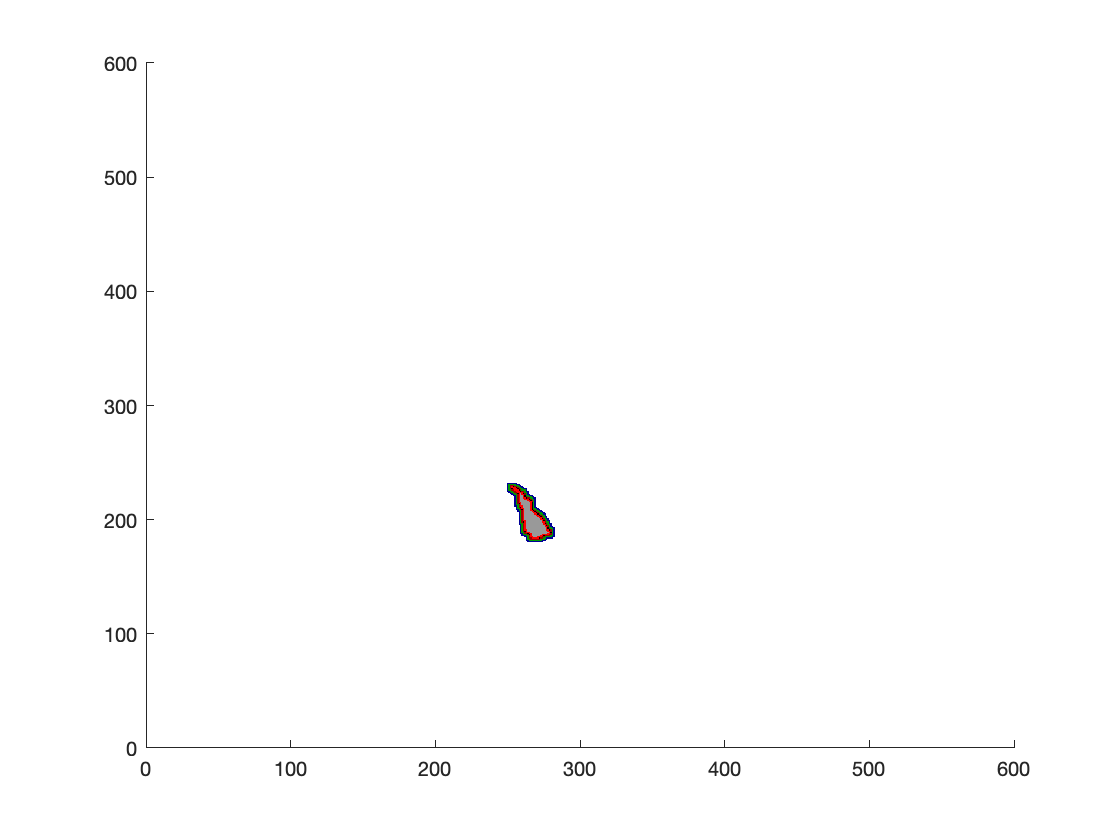

curr_tag_string = '1_comp1_fill'

curr_tag_string = '1_comp1_edgeOffsetIndex_0'

curr_tag_string = '1_comp1_edgeOffsetIndex_1'

curr_tag_string = '1_comp1_edgeOffsetIndex_2'

curr_tag_string = '1_comp1_edgeOffsetIndex_3'

Index exceeds the number of array elements (5).

clf(combinedFig)
combinedOffsetInsetIndicies = [nan, 3, 2, 1, 0, -1, -2, -3];
colorsArray = {lightgrey3DArray, darkBlue3DArray, darkGreen3DArray, darkRed3DArray, black3DArray, red3DArray, green3DArray, blue3DArray};

for i = 1:final_data_explorer_obj.num_cellROIs
    cellROIIdentifier.uniqueRoiIndex = i;
    cellROIIdentifier.roiName = final_data_explorer_obj.cellROIIndex_mapper.getRoiNameFromUniqueCompIndex(i);
    
    for plotImageIndex = 1:length(combinedOffsetInsetIndicies)
        currEdgePlotImageIdentifier.cellROIIdentifier = cellROIIdentifier;
        currEdgePlotImageIdentifier.edgeOffsetIndex = combinedOffsetInsetIndicies(plotImageIndex);
        
        if isnan(currEdgePlotImageIdentifier.edgeOffsetIndex)
            % For the fill layer, the edgeOffsetIndex is nan
            im(plotImageIndex) = image('CData', colorsArray{plotImageIndex}, 'AlphaData', squeeze(final_data_explorer_obj.roiMasks.Fill(i,:,:)));
        else
            im(plotImageIndex) = image('CData', colorsArray{plotImageIndex}, 'AlphaData', final_data_explorer_obj.getEdgeOffsetRoiMasks(currEdgePlotImageIdentifier.edgeOffsetIndex, i));
        end
        
        curr_tag_string = fnBuildCellRoiPlotTagString(combinedOffsetInsetIndicies(plotImageIndex), cellROIIdentifier);
        
        set(im(plotImageIndex), 'UserData', currEdgePlotImageIdentifier);
        set(im(plotImageIndex), 'Tag', curr_tag_string);
        
    end

end

title('Combined Insets and Outsets')
set(gca,'xtick',[],'YTick',[])